# **DC Motor simulation**

## Modeling

### *Need to Know*

Closed - Loop Control

Feedforward Compensation(EMF according to rotation speed)

Final Value Theorem

Pole - Zero Cancelation

Anti - Windup

### *Current PI Control *

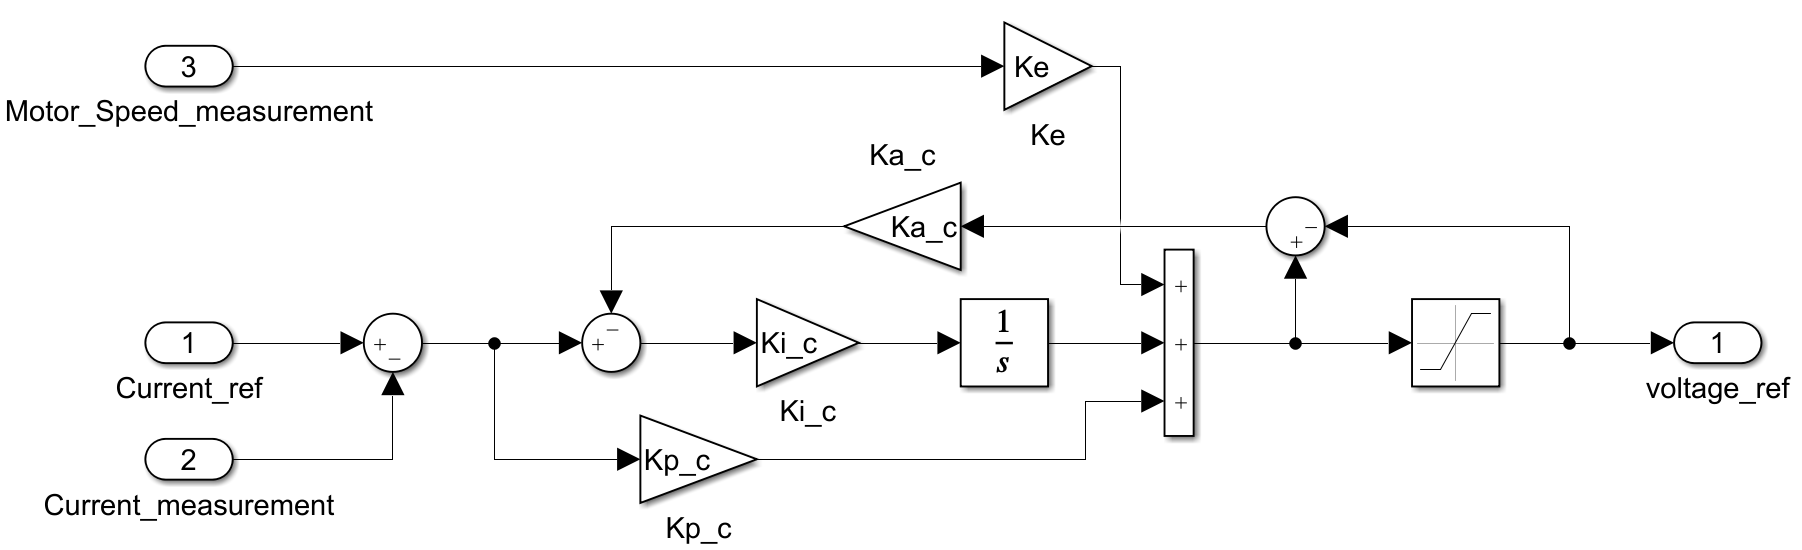

### *Speed PI Control*

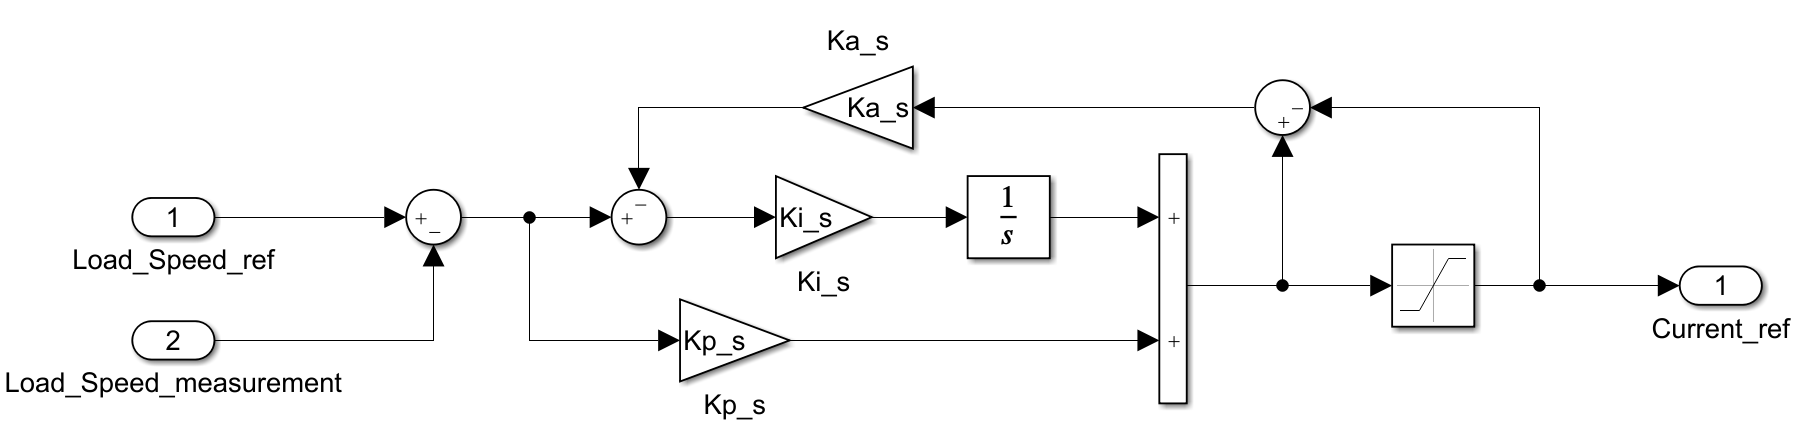

### *Position PD Control*

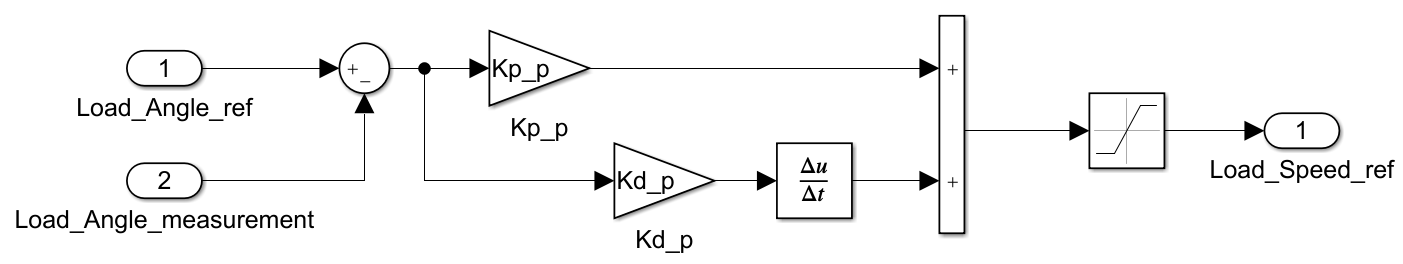

### *Cascade Control System*

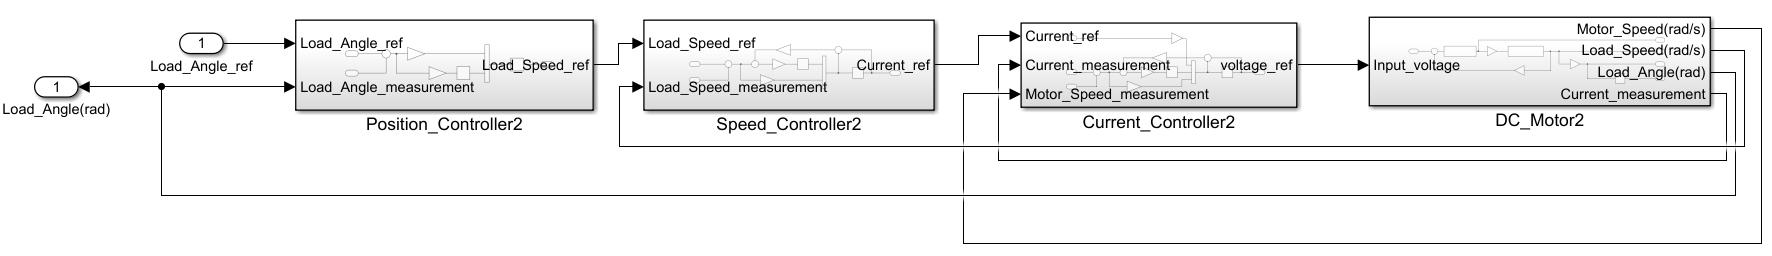

clc; clear;

## Motor Parameter

Va = 48;                    % Input Voltage [V]
Ra = 1.76;                  % Resistance [Ohm]
La = 0.658e-3;              % Inductance [H]
Kt = 68.3e-3;               % Torque Constant [Nm/A]
Ke = Kt;                    % EMF Constnat(Counter Electromotive Force) [Nm/A]
 J = 99.5e-7;               % Rotor inertia [kg^2]
 t = 3.76e-3;               % Mechanical Time Constant [s]
 B = J/t;                   % Friction coefficient [Nm/(rad/s)] 
R2D = 180/pi;
D2R = pi/180;
fcc = 1000;                 % PWM switching freqency / 10

## Bar & Circular Parameter

bar_m = 0.175;                                         % bar mass [kg]
bar_l = 0.3;                                           % bar lengh [m]
bar_h = 0.025;                                         % bar height [m]

cir_m = 0.34;                                          % circular mass [kg]
cir_l = 0.3;                                           % circular length [m] 
cir_r = 0.05;                                          % circular radius [m]

 Jbar = (1/3)*bar_m*(bar_l^2 + (1/4)*bar_h^2);         % bar Inertia [kgm^2]
 Jcir = (1/2)*(cir_m*cir_r^2) + cir_m*(cir_l^2);       % circular Inertia [kgm^2]
Jload = Jbar + Jcir;                                   % bar & circular Inertia [kgm^2]
Bload = Jload/t;                                       % bar & circular Friction Coeffieicnt [Nm/(rad/s)]

## Gear Parameter

alpha = 0.72;                                    % Gear Max Efficiency
   Gr = 1/81;                                    % Gear Ratio
Jgear = 5e-7;                                    % Gear Intertia [Kgm^2]
  Jeq = 1.7631e-05;                              % Motor + Gear + Load Inertia(Gr*Gr/alpha*Jgear + Gr*Gr/alpha*Jload + J) [kgm^2]                                
  Beq = Jeq/t;                                   % Motor + Gear + Load Friction Coefficient [Nm/(rad/s)]

## Current Control(PI Contorl)

Wcc = 2*pi*fcc;                 % (2*pi*1000)

Kp_c = La*Wcc;                  % Current Contorl P Gain
Ki_c = Ra*Wcc;                  % Current Contorl I Gain

Ka_c = 1/Kp_c;                  % Anti-Windup Gain

## Speed Control(PI Control)

Wcs = Wcc/10;                   % (2*pi*1000)/10

Kp_s = Jeq*Wcs/Gr/Kt;           % Speed Contorl P Gain
Ki_s = Beq*Wcs/Gr/Kt;           % Speed Contorl I Gain

Ka_s = 1/Kp_s;                  % Anti-Windup Gain

## Position Control(PD Contorl)

Wcp = Wcs/10;                       % (2*pi*1000)/10/10

Kp_p = Wcp;                         % Position Contorl P Gain
Kd_p = Wcp/Wcs;                     % Position Contorl D Gain

Ka_p = 1/Kp_p;                      % Anti-Windup Gain

## **Graph(Current Control 1A & 5A & 10A & 25A)**

simout = sim('hw3');
figure('Units', 'pixels', 'pos', [100 100 1200 800]);

### 1 [A]

subplot(2,2,1);
plot(simout.cur_m1.time, simout.cur_m1.signals.values, 'LineWidth', 2);
hold on;
plot(simout.cur_m1.time, simout.cur_r1.signals.values, '--', 'LineWidth', 2);

axis([0 0.001 0 2]);
xlabel('t [s]', 'fontsize', 10);
ylabel('Current [A]', 'fontsize', 10);
legend('measurement', 'reference');
title('Current PI Control 1 [A]', 'fontsize', 20);
grid on;

### **5 [A]**

subplot(2,2,2);     
plot(simout.cur_m5.time, simout.cur_m5.signals.values, 'LineWidth', 2);
hold on;
plot(simout.cur_r5.time, simout.cur_r5.signals.values, '--', 'LineWidth', 2);

axis([0 0.001 0 10]);
xlabel('t [s]', 'fontsize', 10);
ylabel('Current [A]', 'fontsize', 10);
legend('measurement', 'reference');
title('Current PI Control 5 [A]', 'fontsize', 20);
grid on;

### 10 [A]

subplot(2,2,3);
plot(simout.cur_m10.time, simout.cur_m10.signals.values, 'LineWidth', 2);
hold on;
plot(simout.cur_r10.time, simout.cur_r10.signals.values, '--', 'LineWidth', 2);

axis([0 0.001 0 20]);
xlabel('t [s]', 'fontsize', 10);
ylabel('current [A]', 'fontsize', 10);
legend('measurement', 'reference');
title('Current PI Control 10 [A]', 'fontsize', 20);
grid on;

### 25 [A]

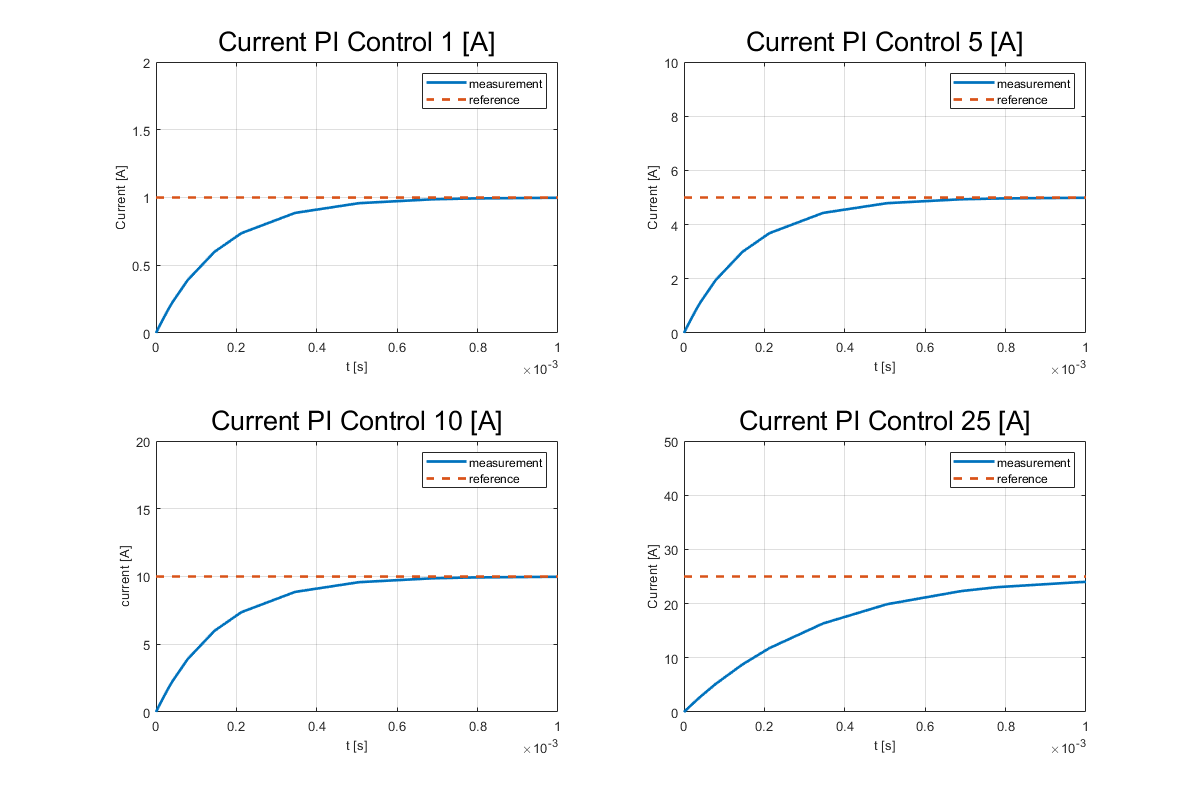

subplot(2,2,4);
plot(simout.cur_m25.time, simout.cur_m25.signals.values, 'LineWidth', 2);
hold on;
plot(simout.cur_r25.time, simout.cur_r25.signals.values, '--', 'LineWidth', 2);

axis([0 0.001 0 50]);
xlabel('t [s]', 'fontsize', 10);
ylabel('Current [A]', 'fontsize', 10);
legend('measurement', 'reference');
title('Current PI Control 25 [A]', 'fontsize', 20);
grid on;

## **Graph(Speed Control 1 [rad/s] & 2 [rad/s] & 3 [rad/s] & 4 [rad/s])**

simout = sim('hw3');
figure('Units', 'pixels', 'pos', [100 100 1200 800]);

### **1 [rad/s]**

subplot(2,2,1);
plot(simout.vel_m1.time, simout.vel_m1.signals.values, 'LineWidth', 2);
hold on;
plot(simout.vel_r1.time, simout.vel_r1.signals.values, '--', 'LineWidth', 2);

axis([0 0.01 0 2]);
xlabel('t [s]', 'fontsize', 10);
ylabel('velocity [rad/s]', 'fontsize', 10);
legend('measurement', 'reference');
title('Speed PI Control 1 [rad/s]', 'fontsize', 20);
grid on;

### **2 [rad/s]**

subplot(2,2,2);
plot(simout.vel_m2.time, simout.vel_m2.signals.values, 'LineWidth', 2);
hold on;
plot(simout.vel_r2.time, simout.vel_r2.signals.values, '--', 'LineWidth', 2);

axis([0 0.01 0 4]);
xlabel('t [s]', 'fontsize', 10);
ylabel('velocity [rad/s]', 'fontsize', 10);
legend('measurement', 'reference');
title('Speed PI Control 2 [rad/s]', 'fontsize', 20);
grid on;

### **3 [rad/s]**

subplot(2,2,3);
plot(simout.vel_m3.time, simout.vel_m3.signals.values, 'LineWidth', 2);
hold on;
plot(simout.vel_r3.time, simout.vel_r3.signals.values, '--', 'LineWidth', 2);

axis([0 0.01 0 6]);
xlabel('t [s]', 'fontsize', 10);
ylabel('velocity [rad/s]', 'fontsize', 10);
legend('measurement', 'reference');
title('Speed PI Control 3 [rad/s]', 'fontsize', 20);
grid on;

### **5 [rad/s]**

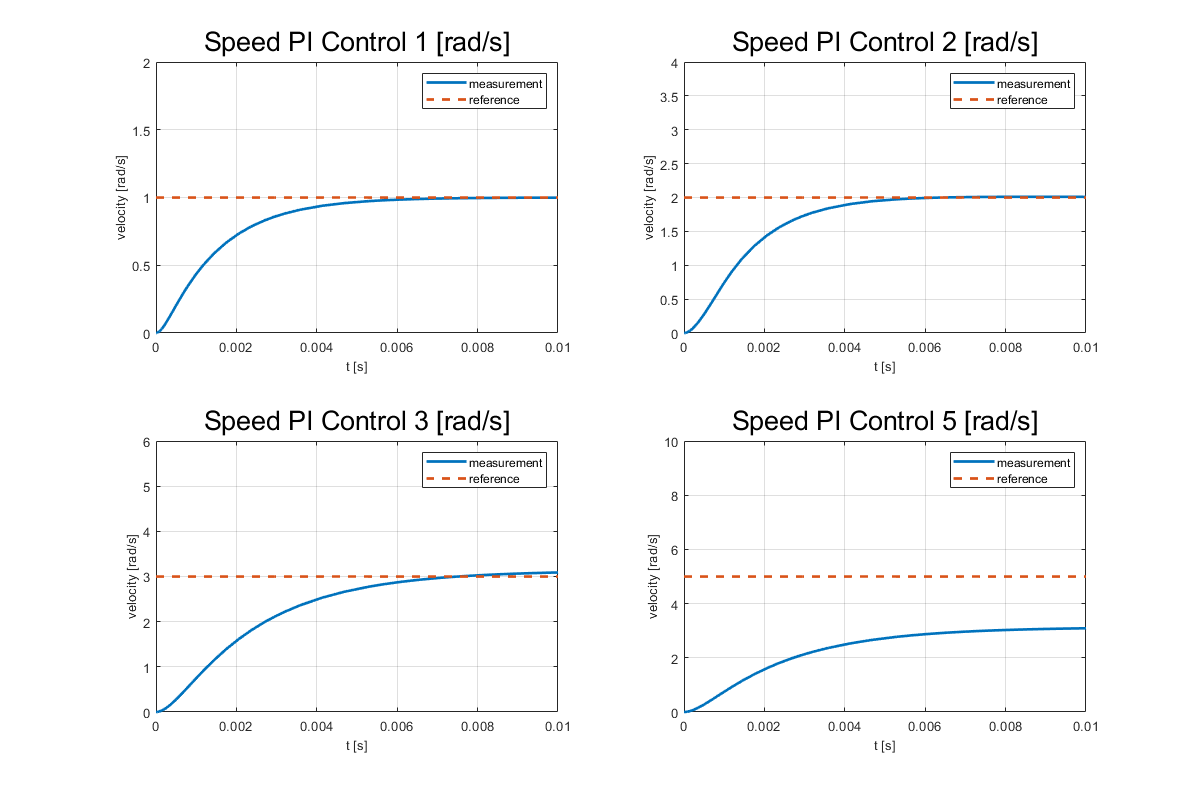

subplot(2,2,4);
plot(simout.vel_m5.time, simout.vel_m5.signals.values, 'LineWidth', 2);
hold on;
plot(simout.vel_r5.time, simout.vel_r5.signals.values, '--', 'LineWidth', 2);

axis([0 0.01 0 10]);
xlabel('t [s]', 'fontsize', 10);
ylabel('velocity [rad/s]', 'fontsize', 10);
legend('measurement', 'reference');
title('Speed PI Control 5 [rad/s]', 'fontsize', 20);
grid on;

## **Graph(Position Control 1 [degree] & 10 [degree] & 45 [degree] & 90 [degree])**

**Not Corrected**

simout = sim('hw3');
figure('Units', 'pixels', 'pos', [100 100 1200 800]);

### **1 [degree]**

subplot(2,2,1);
plot(simout.deg_m1.time, simout.deg_m1.signals.values*R2D, 'LineWidth', 2);
hold on;
plot(simout.deg_r1.time, simout.deg_r1.signals.values*R2D, '--', 'LineWidth', 2);

axis([0 0.1 0 2]);
xlabel('t [s]', 'fontsize', 10);
ylabel('degree', 'fontsize', 10);
legend('measurement', 'reference');
title('Position PD Control 1 [degree]', 'fontsize', 20);
grid on;

### **10 [degree]**

subplot(2,2,2);
plot(simout.deg_m10.time, simout.deg_m10.signals.values*R2D, 'LineWidth', 2);
hold on;
plot(simout.deg_r10.time, simout.deg_r10.signals.values*R2D, '--',  'LineWidth', 2);

axis([0 0.1 0 20]);
xlabel('t [s]', 'fontsize', 10);
ylabel('degree', 'fontsize', 10);
legend('measurement', 'reference');
title('Position PD Control 10 [degree]', 'fontsize', 20);
grid on;

### **45 [degree]**

subplot(2,2,3);
plot(simout.deg_m45.time, simout.deg_m45.signals.values*R2D, 'LineWidth', 2);
hold on;
plot(simout.deg_r45.time, simout.deg_r45.signals.values*R2D, '--',  'LineWidth', 2);

axis([0 0.1 0 90]);
xlabel('t [s]', 'fontsize', 10);
ylabel('degree', 'fontsize', 10);
legend('measurement', 'reference');
title('Position PD Control 45 [degree]', 'fontsize', 20);
grid on;

### **90 [degree]**

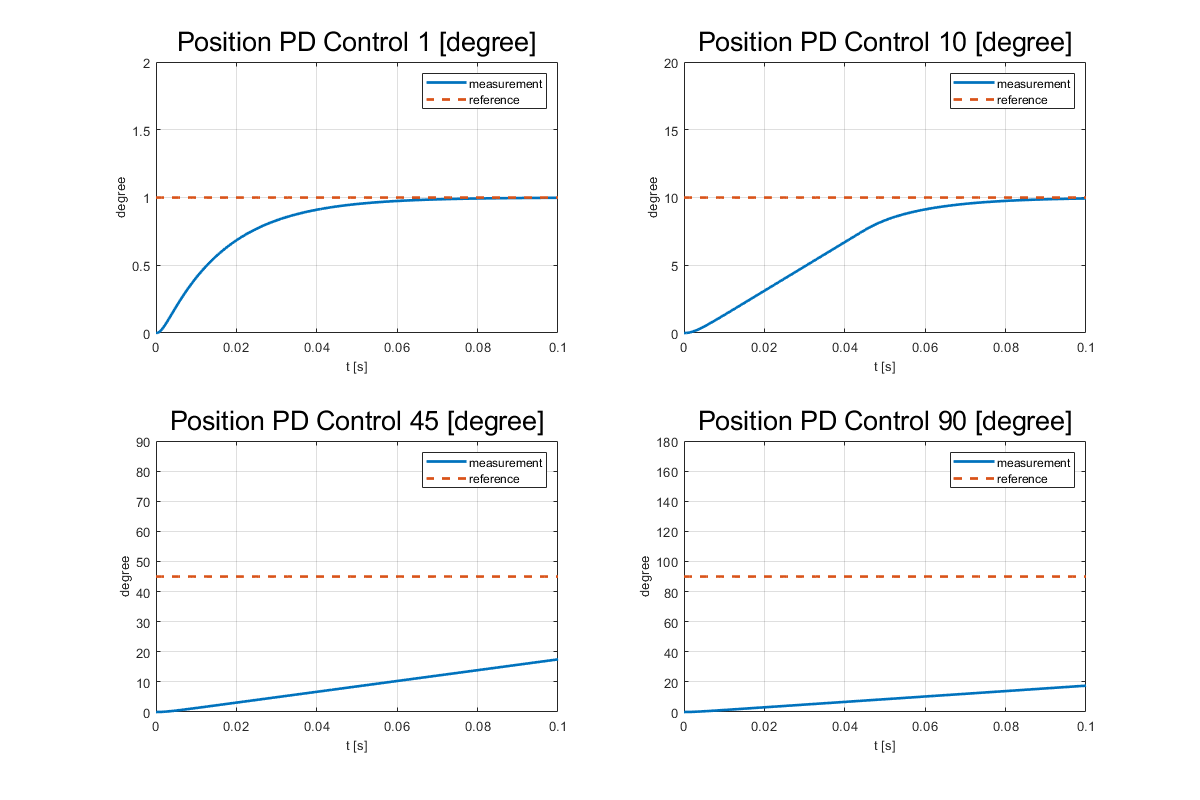

subplot(2,2,4);
plot(simout.deg_m90.time, simout.deg_m90.signals.values*R2D, 'LineWidth', 2);
hold on;
plot(simout.deg_r90.time, simout.deg_r90.signals.values*R2D, '--',  'LineWidth', 2);

axis([0 0.1 0 180]);
xlabel('t [s]', 'fontsize', 10);
ylabel('degree', 'fontsize', 10);
legend('measurement', 'reference');
title('Position PD Control 90 [degree]', 'fontsize', 20);
grid on;

## Cascade Control Result

simout = sim('hw3');
figure('Units', 'pixels', 'pos', [100 100 1800 400]);

### **Angle**

subplot(1,3,1);
plot(simout.CurPos.time, simout.CurPos.signals.values*R2D, 'LineWidth', 2);
hold on;
plot(simout.RefPos.time, simout.RefPos.signals.values*R2D, '--', 'LineWidth', 2);

axis([0 0.5 0 120]);
xlabel('t [s]', 'fontsize', 10);
ylabel('degree', 'fontsize', 10);
legend('measurement', 'reference');
title('Position PD Control', 'fontsize', 20);
grid on;

### **Speed**

subplot(1,3,2);
plot(simout.CurVel.time, simout.CurVel.signals.values, 'LineWidth', 2);
hold on;
plot(simout.RefVel.time, simout.RefVel.signals.values, '--',  'LineWidth', 2);

axis([0 0.5 0 80]);
xlabel('t [s]', 'fontsize', 10);
ylabel('degree', 'fontsize', 10);
legend('measurement', 'reference');
title('Speed PI Control', 'fontsize', 20);
grid on;

### **Current**

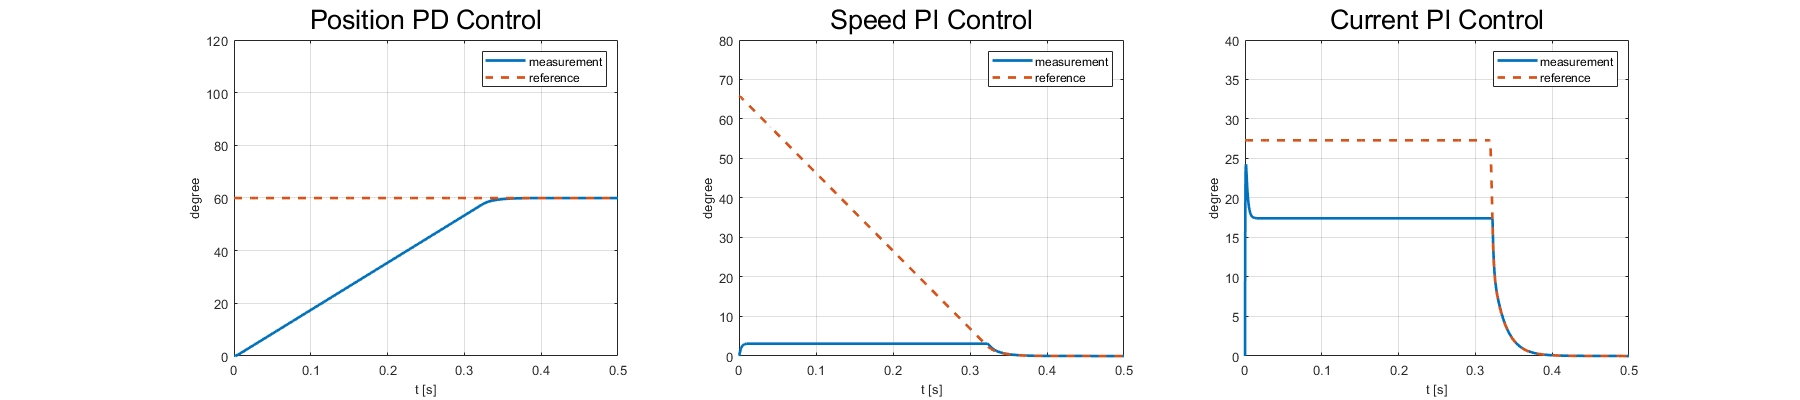

subplot(1,3,3);
plot(simout.CurCur.time, simout.CurCur.signals.values, 'LineWidth', 2);
hold on;
plot(simout.RefCur.time, simout.RefCur.signals.values, '--',  'LineWidth', 2);

axis([0 0.5 0 40]);
xlabel('t [s]', 'fontsize', 10);
ylabel('degree', 'fontsize', 10);
legend('measurement', 'reference');
title('Current PI Control', 'fontsize', 20);
grid on;